# MECH 412 Project: Quadcopter Basketball

This script can be used to initialize the simulation parameters, run the simulation (you can also run within the Simulink model itself), and animate the results. For the animation, you can turn on "Designer Mode" to visualize the thrust inputs, reference position, and flight path. This mode will be useful during your developmental testing, detailed in the Project insturctions.

Youc an also use this script to initiate friendly matches. You can also initiate these matches by running the script "Run_Friendly_Match.m" directly. 

The quadcopter model is identical to Virtual Lab 4, so refer back to those instructions for details about the model. For this project, do not change any of the simulation parameters, initialized here, because they are standardized for the competition. However, you may want to reference them to gain a better sense of how the model works. 

You will likely want to change some of the initial conditions during your testing. I highly recommend only modifying initial conditions using the separate section below called "Modify Initial Conditions for Testing".

## Initialize the Simulation Parameters (Competion standards, do not modify!)

g = 9.81; % (m/s^2)

m = 1; % (kg) mass of drone
r = 0.5; % moment arm of thrust
r_M_R = 0.25*r; % (m) collision moment arm
J = 1/4*m*r^2 + 1/12*m*(2*(r+r_M_R))^2;

T_max = 4*m*g; % (N) max thrust
T_tau = 0.1; % (s) time constant of  motor spin up

T_aux = 0.5*pi*J; % (N) thrust reserved for rotation when saturating thrust input

b = .25*m; % (kg/m) quadratic drag coeff
b_th = .1*J; % (kg-m^2) rotational drag coeff

k_F_R = m * 10000; % (N/m) ground collision stiffness
b_F_R = m * 20; % (N-s/m) ground collision damping

mu_f = .2; % coefficient of friction between ball/drone
mu_f_gnd = 0.5; % coefficient of friction between drone/ground
k_f = 4; % onset rate of coulomb friction 

m_ball = .5; % (kg) mass of ball
r_ball = .3; % (m) radius of ball
J_ball = 2/5*m_ball*r_ball^2; % (kg-m^2) rotational moment of inertia
b_ball = .02*m_ball; % (kg/m) quadratic drag coeff
b_th_ball = .05*J_ball; % (kg-m^2) rotational drag coeffb_ball = .05*m_ball; % (kg/m) linear drag of of ball

k_F_R_ball = m_ball * 10000; % (N/m) ground collision stiffness
b_F_R_ball = m_ball * 10; % (N-s/m) ground collision damping

m_hook = 0.1*m; % (kg) mass of ball
r_hook = 0.1; % (m) effective magnetic distance when in contact with ball
b_hook = 0.05*m_hook; % (kg/m) linear drag coeff
B_hook = r_hook^2*6*m_ball*g; % (N-m^2) strength of magnet
k_F_R_hook = m_hook * 10000; % (N/m) ground collision stiffness
b_F_R_hook = m_hook * 100; % (N-s/m) ground collision damping

L_tether = 1.0; % (m) tether length
k_tether = 40; % (N/m) tether stiffness
b_tether = 1; % (N-s/m) tether damping

k_F_hook = 10000; % (N/m) tether stiffness
b_F_hook = 100;

k_F_hoop = m_ball * 5000; % (N/m) hoop stiffness
b_F_hoop = m_ball * 50;

k_x_net = 200*m_ball*g;
b_x_net = 80*m_ball*g;
k_y_net = .5*m_ball*g;
b_y_net = .4*m_ball*g;

p_0 = [-5; 5]; % initial position of each drone (mirrored)
theta_0 = 0 * pi/180; % (rad) initial angle

p_dot_0 = [0; 0]; % (m/s) initial [x;y] velocity
theta_dot_0 = 0; % (rad/s) initial angular velocity

drone = struct([]);

drone(1).X_0 = [p_0(1) p_dot_0(1) p_0(2) p_dot_0(2) theta_0 theta_dot_0]';
drone(2).X_0 = drone(1).X_0 .* [-1 -1 1 1 -1 -1]'; % mirrored

T_0 = m*g; % (N) initial thrust

p_ball_0 = [0; r_ball]; % (m) initial [x;y] position

p_ball_dot_0 = [0; 12]; % (m/s) initial [x;y] velocity (jump ball)

p_tether = [0; -0.259]; % (m) position of tether attatchment (matches graphic)

p_emp = [0; -.4]; % (m) emp cannon location
p_emp_dot = [0; -5]; % (m/s) emp velocity

p_hoop = [7.5 8; 8.5 8; -8.5 8; -7.5 8]';

### Modify Initial Conditions for Testing

If you want to change some of the intiial conditions during testing, I recommend only changing them here. This way you can avoid changing the initial conditions in the section above, which are the competiion standards.

p_0 = [-5; 5]; % initial position of each drone (mirrored)
theta_0 = 0 * pi/180; % (rad) initial angle

p_dot_0 = [0; 0]; % (m/s) initial [x;y] velocity
theta_dot_0 = 0; % (rad/s) initial angular velocity

drone = struct([]);

drone(1).X_0 = [p_0(1) p_dot_0(1) p_0(2) p_dot_0(2) theta_0 theta_dot_0]';
drone(2).X_0 = drone(1).X_0 .* [-1 -1 1 1 -1 -1]'; % mirrored

T_0 = m*g; % (N) initial thrust

p_ball_0 = [0; r_ball]; % (m) initial [x;y] position

p_ball_dot_0 = [0; 12]; % (m/s) initial [x;y] velocity (jump ball)

p_tether = [0; -0.259]; % (m) position of tether attatchment (matches graphic)

p_emp = [0; -.4]; % (m) emp cannon location
p_emp_dot = [0; -5]; % (m/s) emp velocity

p_hoop = [7.5 8; 8.5 8; -8.5 8; -7.5 8]';

### Run the Simulation

This command has been tempermental, sometimes saving the ToWorkspace variabes in a structure, which doesn't work with the animation function below. I recommend running the simulink model by pressing the green "Run" button in Simullink.

sim('Drone_BBall_Developer.slx');

*You will likely get a warning about contructing a fi object. I haven't been able to figure this one out yet, but everything works just fine :p*

### Animate the Results

Plays through one period of the Drone Basketball match. You can press CTRL+C at any time to stop execution.

Change the framerate 

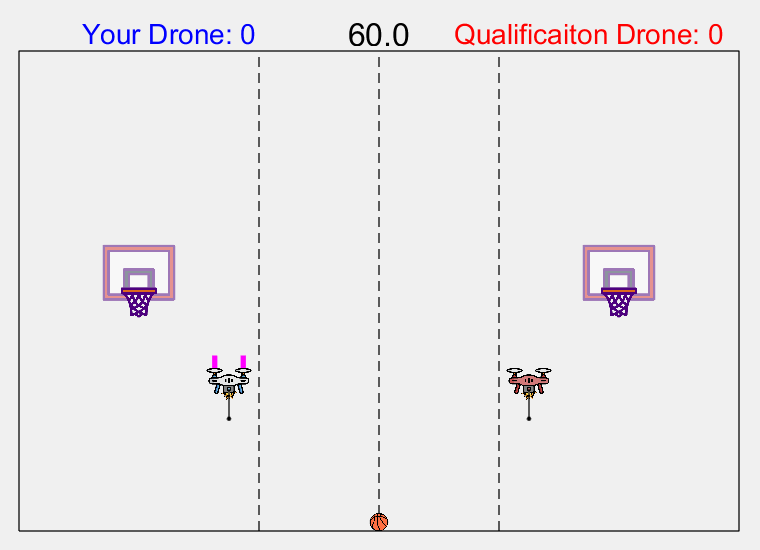

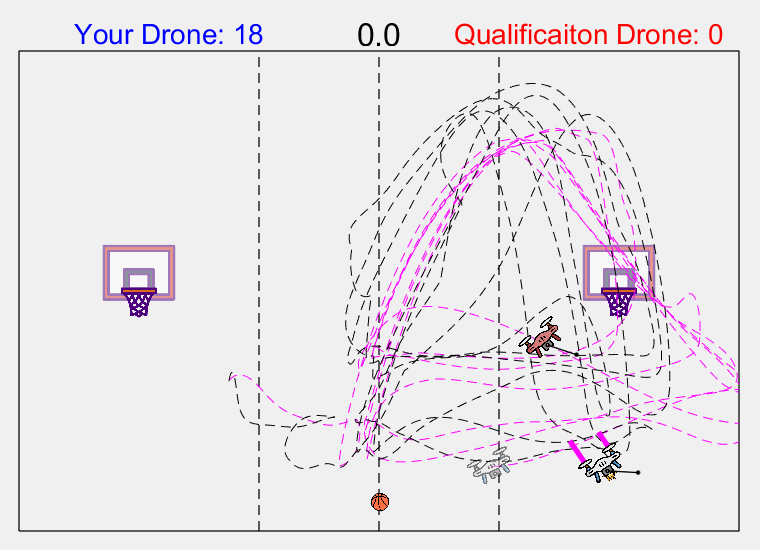

plot_options.drone_1_name = 'Your Drone';
plot_options.drone_2_name = 'Qualificaiton Drone';
plot_options.fps = 5; % set the framerate

plot_options.fig = 1; % reserve figure 1 for animations

plot_options.resolution  = 4;  % image resolution scale (default = 4)
plot_options.save_movie  = 0;  % disable this for faster video
plot_options.design_mode = 1;  % 1 = Designer Mode (show thrust and flight paths)
plot_options.full_screen = 0;  % doesn't work the first time if figure not already open
plot_options.window_size = 720;

sim_data.p_tether       = p_tether;
sim_data.p_hoop         = p_hoop;
sim_data.message        = 0; % no special game text

sim_data.t_max          = max(t);
sim_data.t              = t;
sim_data.X_drone_t      = X_drone_t;
sim_data.X_hook_t       = X_hook_t;
sim_data.X_ball_t       = X_ball_t;
sim_data.X_emp_t        = X_emp_t;
sim_data.stunned_t      = stunned_t;
sim_data.score_t        = score_t;
sim_data.emp_visible_t  = double(emp_visible_t);

sim_data.u_t   = T_t/(.5*m*g);
sim_data.X_d_t = X_d_t;

[F,performance_log] = animate_drone_bball(sim_data,plot_options);

### Replay the Animation

 Once you have created F using the section above (or below) you can run this section to replay the animation in real time.

figure(plot_options.fig)
movie(F,1,plot_options.fps)

Error using movie
Movie contains uninitialized frames

Error in movie

Error in movie

Error in movie

Error in movie

### Play a Full Match

In the script "Run_Match.m" you can toggle which Simulink model is used to run the match. When testsing your controller agains the Qualification Drone, you can use the model "Drone_BBall_Developer.slx". During friendly matches, you can use the model "Drone_BBall_Friendly.slx" so that you don't have to modify your "Drone_BBall_Developer.slx" model. 

clear % deletes all variables, all necessary variables are set by Run_Friendly_Match.m

plot_options.drone_1_name = 'Your Drone';
plot_options.drone_2_name = 'Qualification Drone';
plot_options.fps = 4; % set the preview framerate (if >=10, the preview will be skipped)

create_video_file = 0; % set to 1 to save a 10 fps video file afterward 

model = 'Drone_BBall_Developer.slx'; % use the developer model
% model = 'Drone_BBall_Friendly.slx'; % use the friendly match model

Run_Match;